# van der Pol oscillator

The van der Pol oscillator is given by 


$$y''+y-\mu(1-y^2)y' = 0,$$


where $\mu$ is a positive parameter. It models nonlinear circuit elements (diodes) and is more generally known as well.

Note that the "spring" term here is linear, and the nonlinearity is in what we usually think of as the "damping" term. However, when $|y|<1$this term is actually feeding energy in, only to switch back to damping when $|y|>1$. As a result, the motion is attracted to a periodic solution called a *limit cycle.*

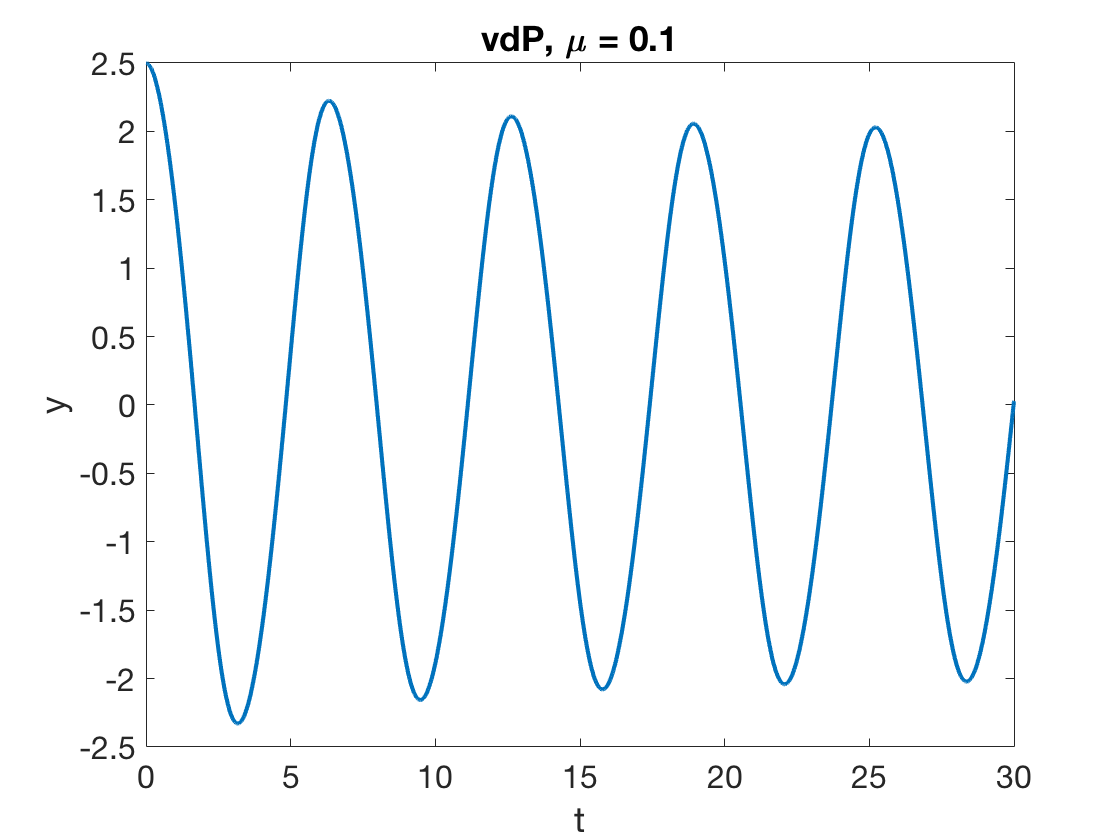

mu = 0.1;
vdP = chebop(@(y) diff(y,2)+y-mu*(1-y^2)*diff(y),[0,30],[2.5 0],[]);
y =vdP\0;  plot(y)
xlabel t, ylabel y
title('vdP, \mu = 0.1')

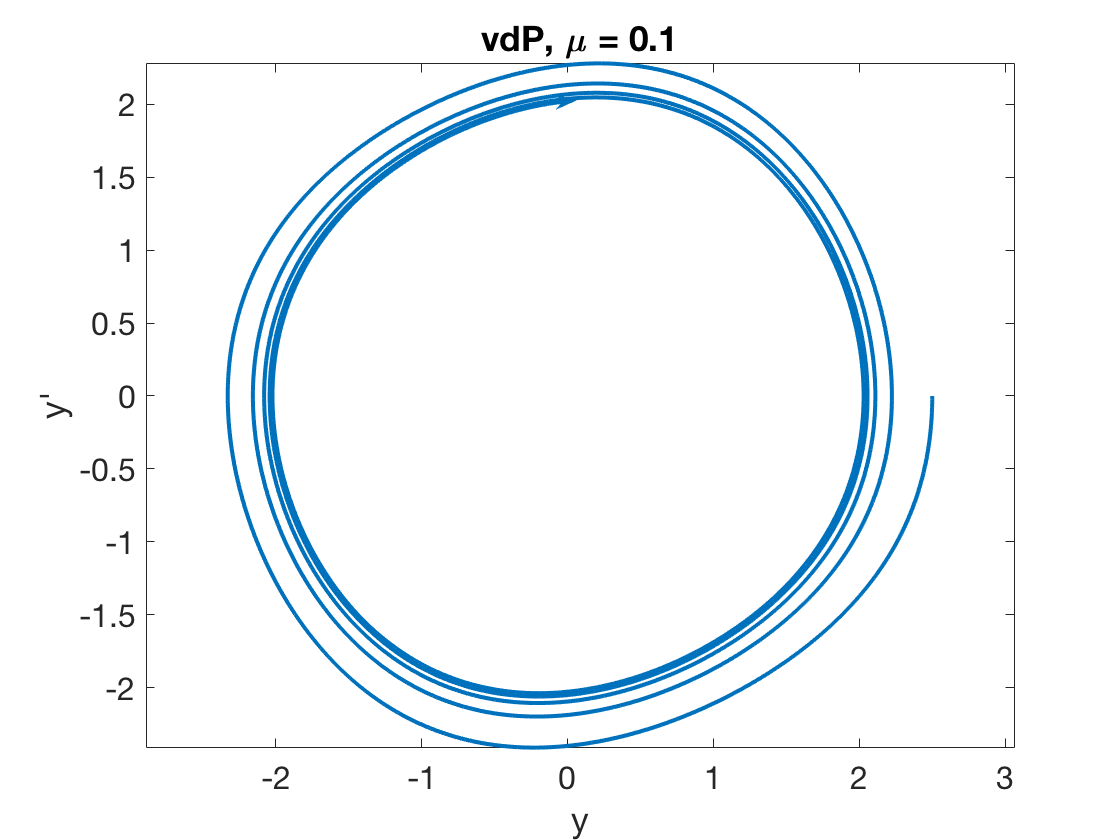

arrowplot(y,diff(y))
xlabel y, ylabel('y''')
title('vdP, \mu = 0.1')
axis equal

As $\mu$ increases, the convergence to the limit cycle is more rapid.

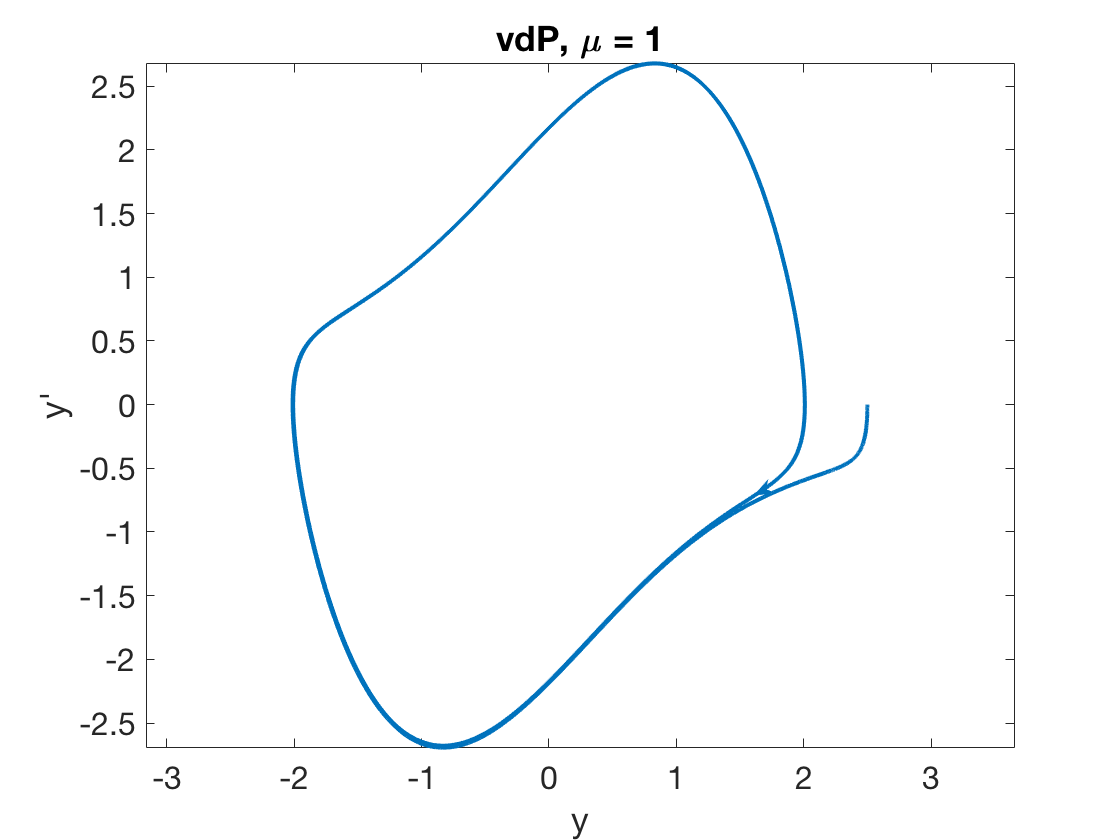

mu = 1;
vdP = chebop(@(y) diff(y,2)+y-mu*(1-y^2)*diff(y),[0,15],[2.5 0],[]);
y =vdP\0;
arrowplot(y,diff(y))
xlabel y, ylabel('y''')
title('vdP, \mu = 1')
axis equal

In addition, the period lengthens, and the system undergoes alternating slow/fast motions.

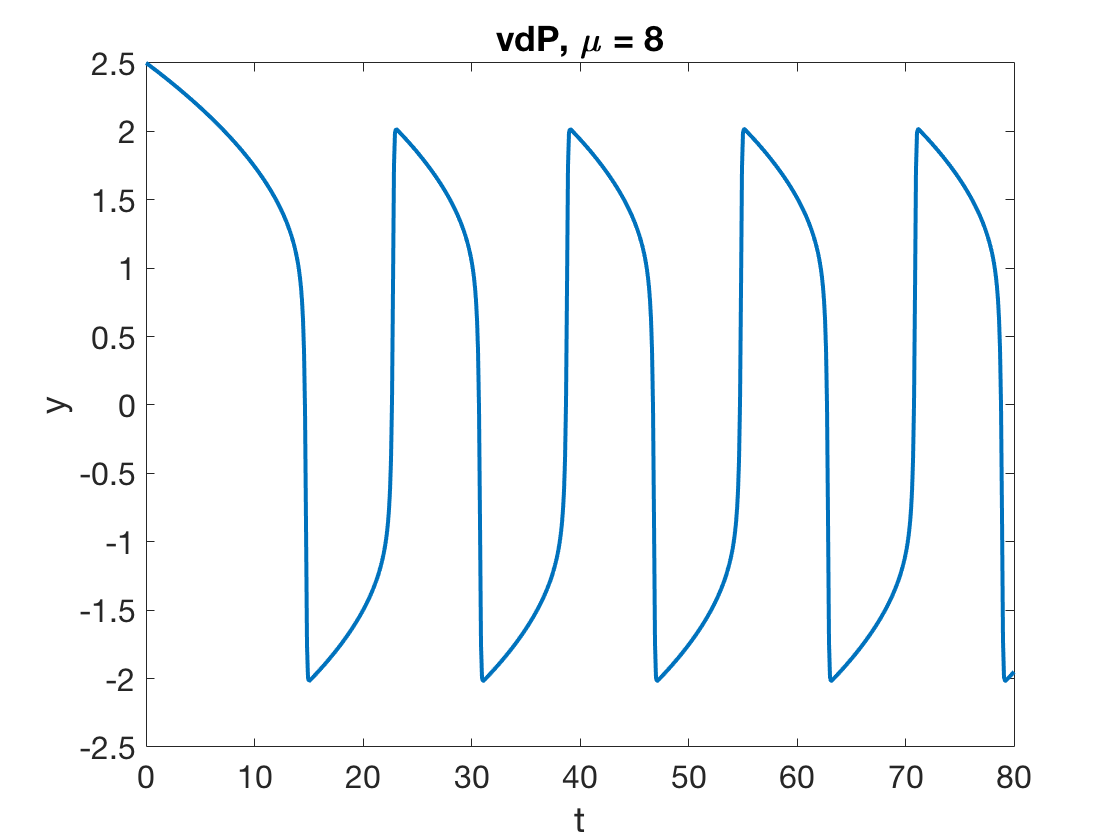

mu = 8;
vdP = chebop(@(y) diff(y,2)+y-mu*(1-y^2)*diff(y),[0,80],[2.5 0],[]);
y =vdP\0;
plot(y)
xlabel t, ylabel y
title('vdP, \mu = 8')